# Lab Assignements #2

cd C:\Users\snjn\OneDrive\Dokument\DigitalBildbehandling\Lab2\

### **1 Setup**

clear all; close all; clc;

addpath('extra_test_images')
tif_files = dir("extra_test_images/*.tif");
png_files = dir("extra_test_images/*.png");
image_files = [tif_files;png_files]

image_files = 5×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


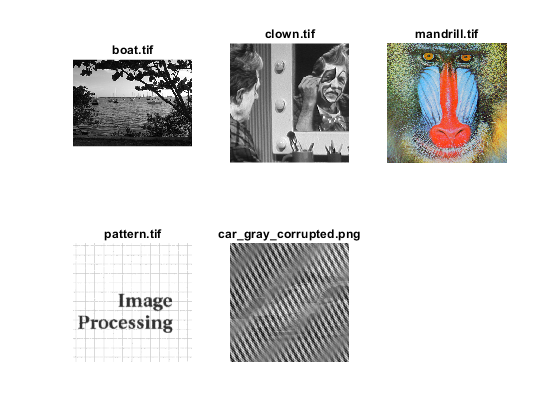


num_rows = floor(sqrt(length(image_files)));
num_columns = ceil(sqrt(length(image_files)));
figure
for i = 1:length(image_files)
    subplot(num_rows, num_columns, i);
    I = imread(image_files(i).name);
    imshow(I); title(image_files(i).name, 'Interpreter', 'none');
end

### **1 ** Linear Spatial Filtering

### **    1.1 **Convolution Operator

clear all; close all; clc;
gauss_mask = fspecial('gaussian', 3, 0.849);

tif_files = dir("extra_test_images/*.tif");
png_files = dir("extra_test_images/*.png");
image_files = [tif_files;png_files];

kernel = gauss_mask

kernel =     0.0625    0.1250    0.0625
    0.1250    0.2501    0.1250
    0.0625    0.1250    0.0625


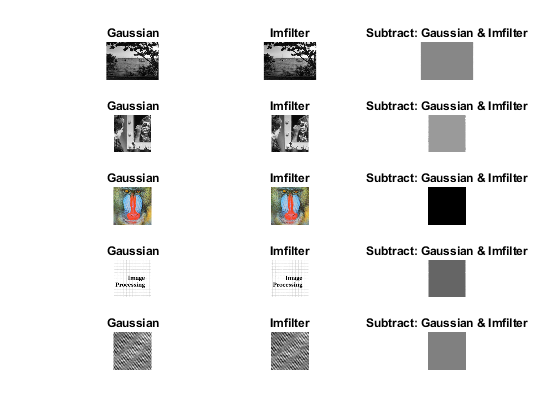


num_rows = length(image_files);
num_columns = 3;
figure
for i = 1:length(image_files)
    I = im2double(imread(image_files(i).name));
    
    subplot(num_rows, num_columns, num_columns * i - 2);
    img_out = convolution_operator(I, kernel); %mirror at border
    imshow(img_out, []); title('Gaussian', 'Interpreter', 'none');
    
    subplot(num_rows, num_columns, num_columns * i - 1);
    img_filter = imfilter(I, kernel, 'symmetric'); %mirror at border
    imshow(img_filter, []); title('Imfilter', 'Interpreter', 'none');
    
    subplot(num_rows, num_columns, num_columns * i - 0);
    imshow(img_filter - img_out, []); title('Subtract: Gaussian & Imfilter', 'Interpreter', 'none');
end

### **    1.2 **Smoothing Filters

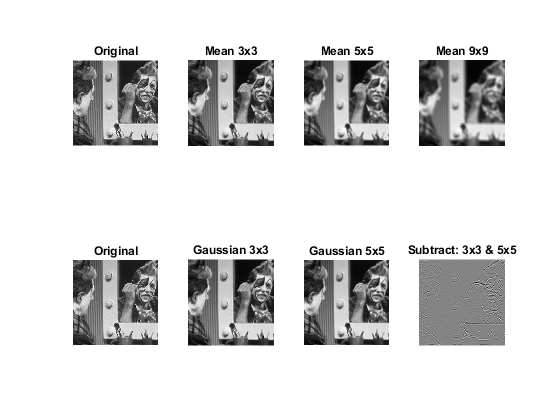

clear all; close all; clc;

I = im2double(imread("clown.tif"));


figure
subplot(2, 4, 1);
imshow(I);title('Original', 'Interpreter', 'none');

subplot(2, 4, 2);
img_mean_3 = convolution_operator(I, fspecial('average', 3));
imshow(img_mean_3, []); title('Mean 3x3', 'Interpreter', 'none');

subplot(2, 4, 3);
img_mean_5 = convolution_operator(I, fspecial('average', 5));
imshow(img_mean_5, []); title('Mean 5x5', 'Interpreter', 'none');

subplot(2, 4, 4);
img_mean_9 = convolution_operator(I, fspecial('average', 9));
imshow(img_mean_9, []); title('Mean 9x9', 'Interpreter', 'none');

subplot(2, 4, 5);
imshow(I);title('Original', 'Interpreter', 'none');

sigma = 0.849;
subplot(2, 4, 6);
img_gauss_3 = convolution_operator(I, fspecial('gaussian', 3, sigma));
imshow(img_gauss_3, []); title('Gaussian 3x3', 'Interpreter', 'none');

subplot(2, 4, 7);
img_gauss_5 = convolution_operator(I, fspecial('gaussian', 5, sigma));
imshow(img_gauss_5, []); title('Gaussian 5x5', 'Interpreter', 'none');

subplot(2, 4, 8);
imshow(img_gauss_3 - img_gauss_5, []); title('Subtract: 3x3 & 5x5', 'Interpreter', 'none');

### **    1.3 **Edge Filters

clear all; close all; clc;

I = im2double(imread("clown.tif"));


figure
subplot(1, 2, 1);
kernel = fspecial('sobel')

kernel =      1     2     1
     0     0     0
    -1    -2    -1


img_out = convolution_operator(I, kernel); %mirror at border
imshow(img_out, []); title('Sobel', 'Interpreter', 'none');

subplot(1, 2, 2);
kernel = fspecial('laplacian')

kernel =     0.1667    0.6667    0.1667
    0.6667   -3.3333    0.6667
    0.1667    0.6667    0.1667


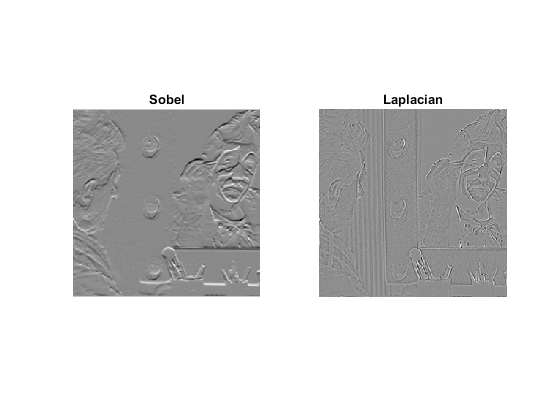

img_out = convolution_operator(I, kernel); %mirror at border
imshow(img_out, []); title('Laplacian', 'Interpreter', 'none');

### **2 **Bilateral Filtering

clear all; close all; clc;



### **3 **Fourier Transform

### **    3.1 **Phase and Magnitude

clear all; close all; clc;



### **    3.2 **Phase vs Magnitude

clear all; close all; clc;



### 4 Filtering in the frequency domain 

###     4.1 “Notch” Filter 

clear all; close all; clc;



###     4.2 SÄPO task

clear all; close all; clc;

